# Paper2 Fig3

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))


close all

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','Larger','LARGER'};

## 3. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;

ICTestAll = cell(2,1);

Background

ICData = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang0.0.mat')]);
LDEbgIC = ICData.LDEEquv;
LDEbgIC.S(:) = 2.5;
LDEbgIC.C(:) = 8;
LDEbgIC.I(:) = 18; %16
ICTestAll{1} = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;


LDEICPart = HCRot(LDEICPart,0,N_HCOut,NPixX,NPixY,0);
ICTestAll{2} = LDEICPart;
LDEOutAll = cell(size(ICTestAll));

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

Hyperparameters of iterations

p = 0.33;% 1-p for the original input
EpocTest = 300;
ExportFlag = 'xn';

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

AngleTestAll = [0 60]; % 0:7.5:22.5; % has to be multiples of 7.5
N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

## Two tests for Fig3

Choose from the list, but input can take everything between 0-180


for TestId = 1:length(AngleTestAll)
    AngleInpt = AngleTestAll(TestId)
    
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

    L4EmeshXAll = cell(size(DomList));
    L4ImeshYAll = cell(size(DomList));
    LDEFrfuncAll = cell(size(DomList));
    for DomInd = 1:length(DomList)
        FuncTemp = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
            'LDEFrfunc','L4EmeshX','L4ImeshY');
        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
    end
    

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 4; L6list = 4;

### ##Note: This small subsec is unused. And should be cos instead of sin

    Grating = Angle; % degree
    GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
    LGNS_biphase = [45+abs(mod(GratingHC,180)-90)/2;
        45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;
    
    L6Ord_F_Grating = min(L6Ord_F) + ...
        (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
    L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
    L6C_Drive_Grating = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac; % only for investigation purpose

LGN and L6 are blurred 

    FigOn = false;
    L6smear = n_S_HC*0.34; LGNsmear = n_S_HC*0.2;
    TruncL6 = 1.25; TruncLGN = 1;
    L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
        N_HC,n_S_HC,L6smear,TruncL6,FigOn);
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
        N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);
    
    PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
    PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

    MirInd = logical(MirInd);
    for Ctgr = 1:4
        PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
        PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
    end
    
    PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
    for PixInd = 1:PixNumOut
        PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
    end

Get pixelwise connectivities

    C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Firing rate suppresion

    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
    %
    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

    tic
    ICUse = ICTestAll{TestId}; % 
    IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);
    

start iteration

    [LDEOutAll{TestId},~,~,~,~,FuncUse] = ...
        LDEIteration_16FuncMain_CombDom(...
        PixInptCtgrUse,IniTest,p,EpocTest,...
        C_SS_mean,C_CS_mean,C_IS_mean,...
        C_SC_mean,C_CC_mean,C_IC_mean,...
        C_SI_mean,C_CI_mean,C_II_mean,...
        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
        N_HCOut,NPixX,NPixY,false,'xn')  ;
    LDEEquv = LDEOutAll{TestId}{end};
    
    
    for EpcInd = 1:EpocTest+1
        LDEPertRslt = LDEOutAll{TestId}{EpcInd};
        SDiff = LDEPertRslt.S - LDEEquv.S;
        SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        CDiff = LDEPertRslt.C - LDEEquv.C;
        CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        IDiff = LDEPertRslt.I - LDEEquv.I;
        IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
        IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
        
        L2Diff_OneStepAll(TestId,EpcInd) = ...
            sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
        DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
    end

    Comment below if don't need to save data (usually for setting up new NESSs)

%     save([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang%s.mat',AngPrint)],...
%     'LDEEquv')   

    toc
end
save([DataFolder 'Fig3AB_data.mat'],'LDEOutAll','L2Diff_OneStepAll','DiffVecAll')

## 4. Make Fig3

load([DataFolder 'Fig3AB_data.mat'],'LDEOutAll','L2Diff_OneStepAll','DiffVecAll')
Panel2All = [4,4,4];
Sufix = {'','','IC'};
AngleTestAll = [0 60 0];
TestUse = [1 2 1];
for TestInd = 1:3
    AngleInpt = AngleTestAll(TestInd);
    Fig3 = figure("Name",sprintf('%.1f',AngleInpt),'units','normalized','outerposition',[0,0,0.5,0.64]);
    %figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.5,0.4]);    
    EpocListAll{1} = [2:8 10];
    EpocListAll{2} = [1:5, 9]; % for angles
    EpocListAll{3} = 1;
    EpocList = EpocListAll{TestInd};
    
    Panel1 = 2; Panel2 = Panel2All(TestInd);%length(EpocList);
    ha = tight_subplot(Panel1,Panel2,[.03 .03],[.08 .08],[.10 .10]);
    LDEEpoOut = LDEOutAll{TestUse(TestInd)};
    CaxeAll{1} = [repmat([0 70],4,1);repmat([5 43],4,1)];
    CaxeAll{2} = [repmat([5 35],10,1)];
    CaxeAll{3} = [0 70];
    Caxe = CaxeAll{TestInd};
    for EpocInd = 1:length(EpocList)
        Epoc = EpocList(EpocInd);
        %subplot(2,6,EpocInd+6*(ICInd-1))
        axes(ha(EpocInd));
        LDEPlot = LDEEpoOut{Epoc};
        ShowField(...
            LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
            1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
            sprintf('Iteration %d',Epoc-1), Caxe(EpocInd,:)) % last input may catgorized cbar: ,, [5 60]
        set(gca,'fontsize',16)
        set(gca,'YTickLabel',[]);
        set(gca,'XTickLabel',[]);
        xlabel(sprintf('$$|x(%d) - x^*|_E = %.2f$$',...
            Epoc-1 , L2Diff_OneStepAll(TestUse(TestInd),Epoc)/(sqrt(NPixX*NPixY))),...
            'Interpreter',"latex")
        colorbar off
        if mod(EpocInd,Panel2) == 0
            Pos1 = get(gca,'Position');
            cbr1 = colorbar(gca, 'Position', [Pos1(1)+Pos1(3)+0.04  Pos1(2)  0.01  Pos1(4)]);
            caxis(Caxe(EpocInd,:))
            set(cbr1,'FontSize',13)
            
        end
    end
    

Save figures

    FigName1 = sprintf('Figure3Draft_%ddeg_NewSmear%s',AngleInpt,Sufix{TestInd});
    savefig(Fig3,[FigurePaperPath FigName1 '.fig']);
    

Print Figs

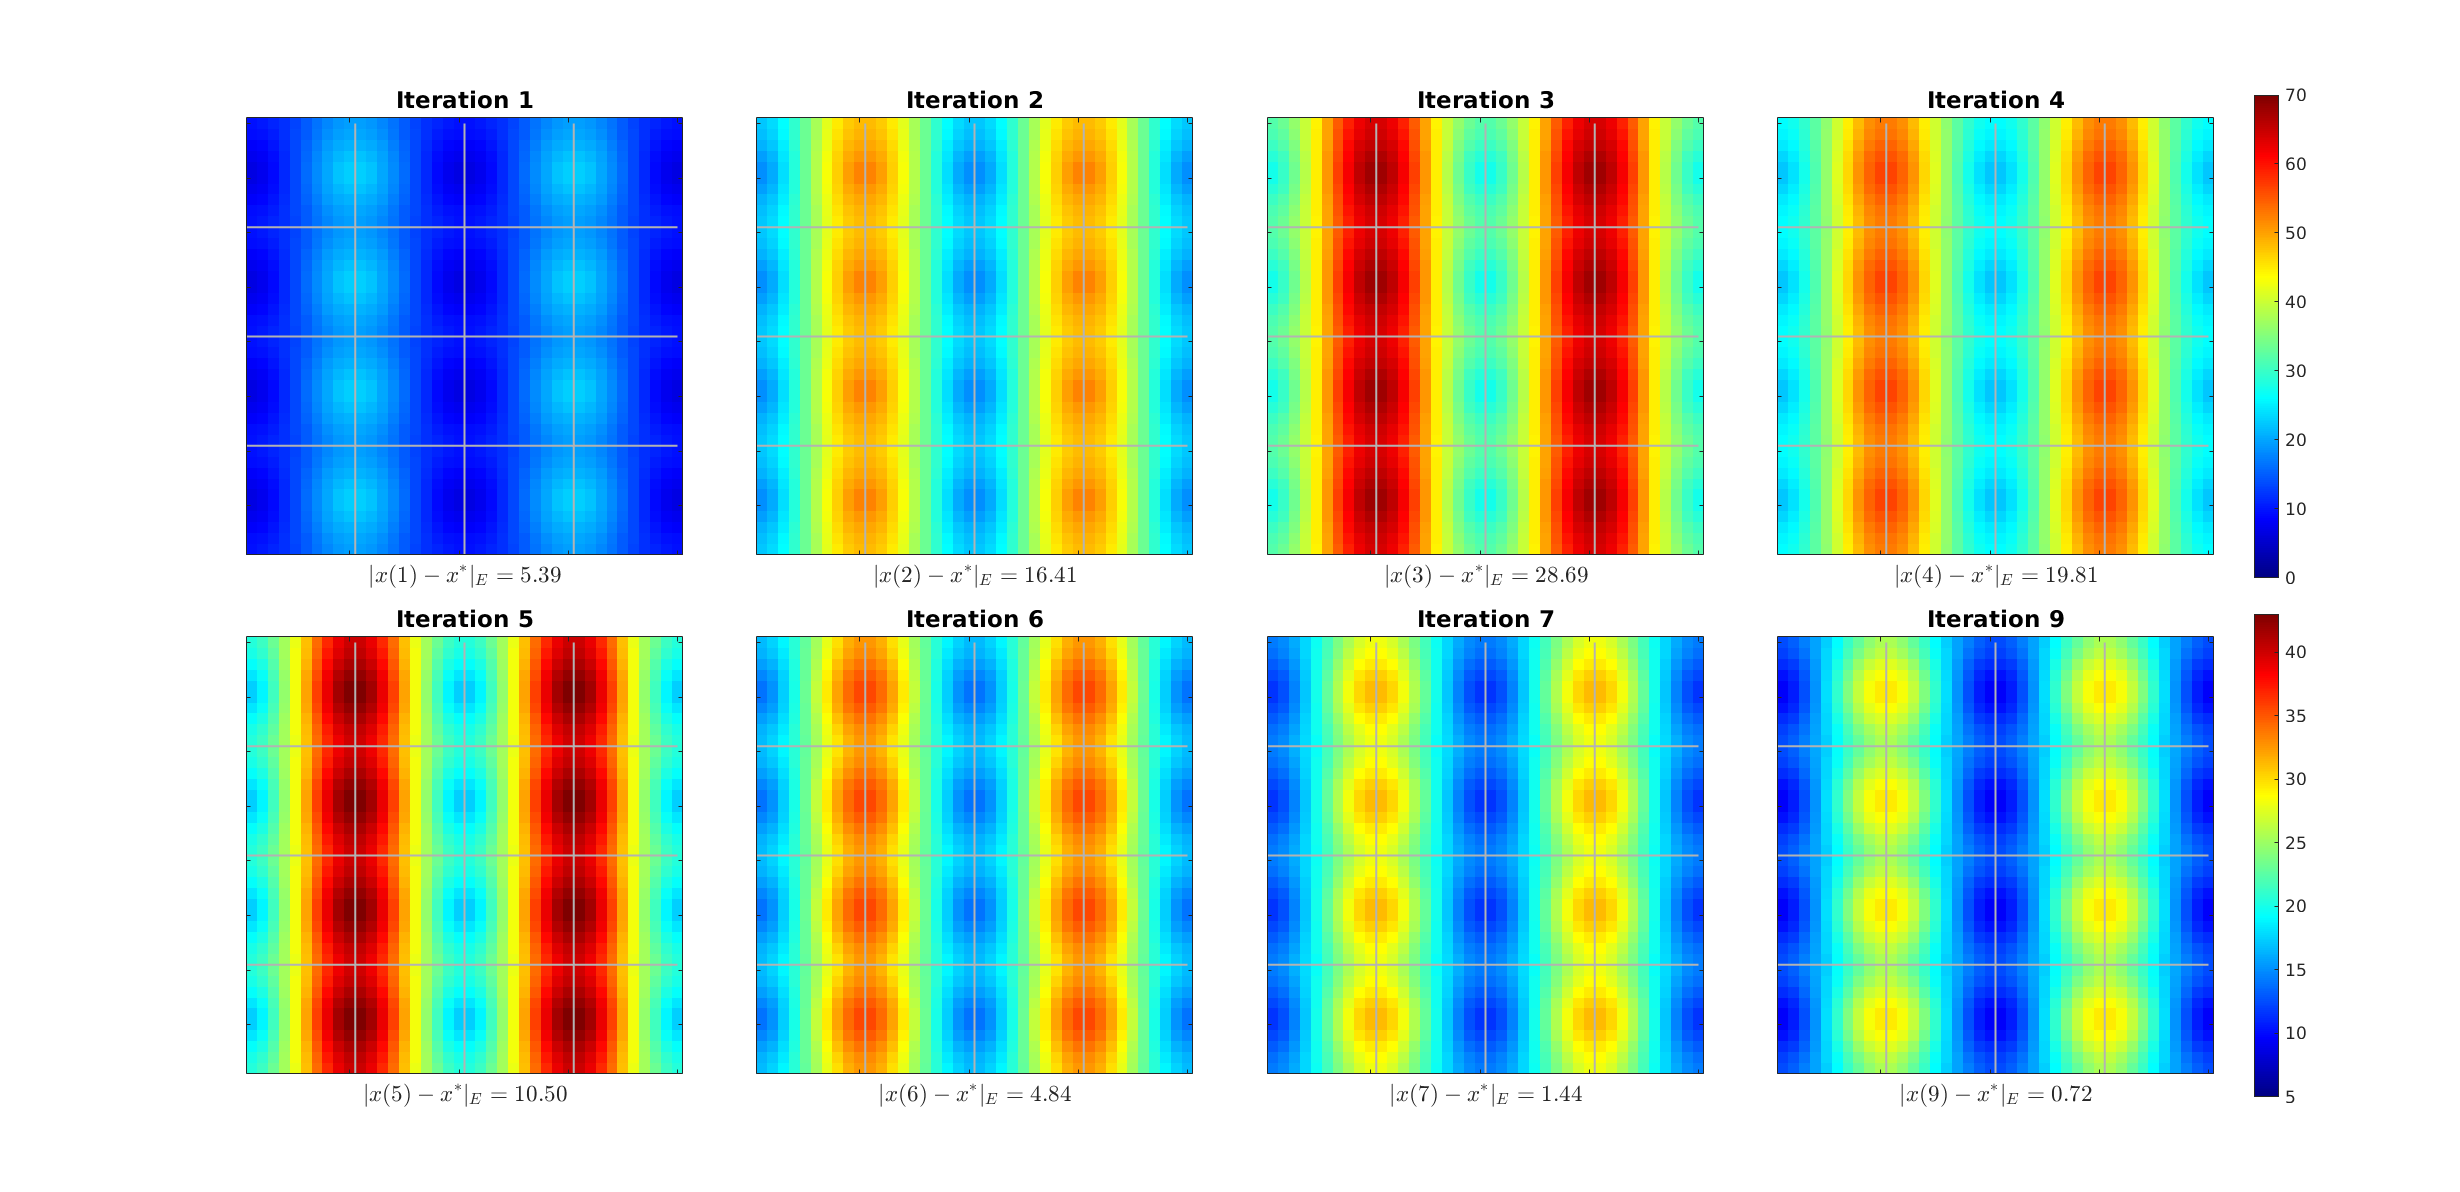

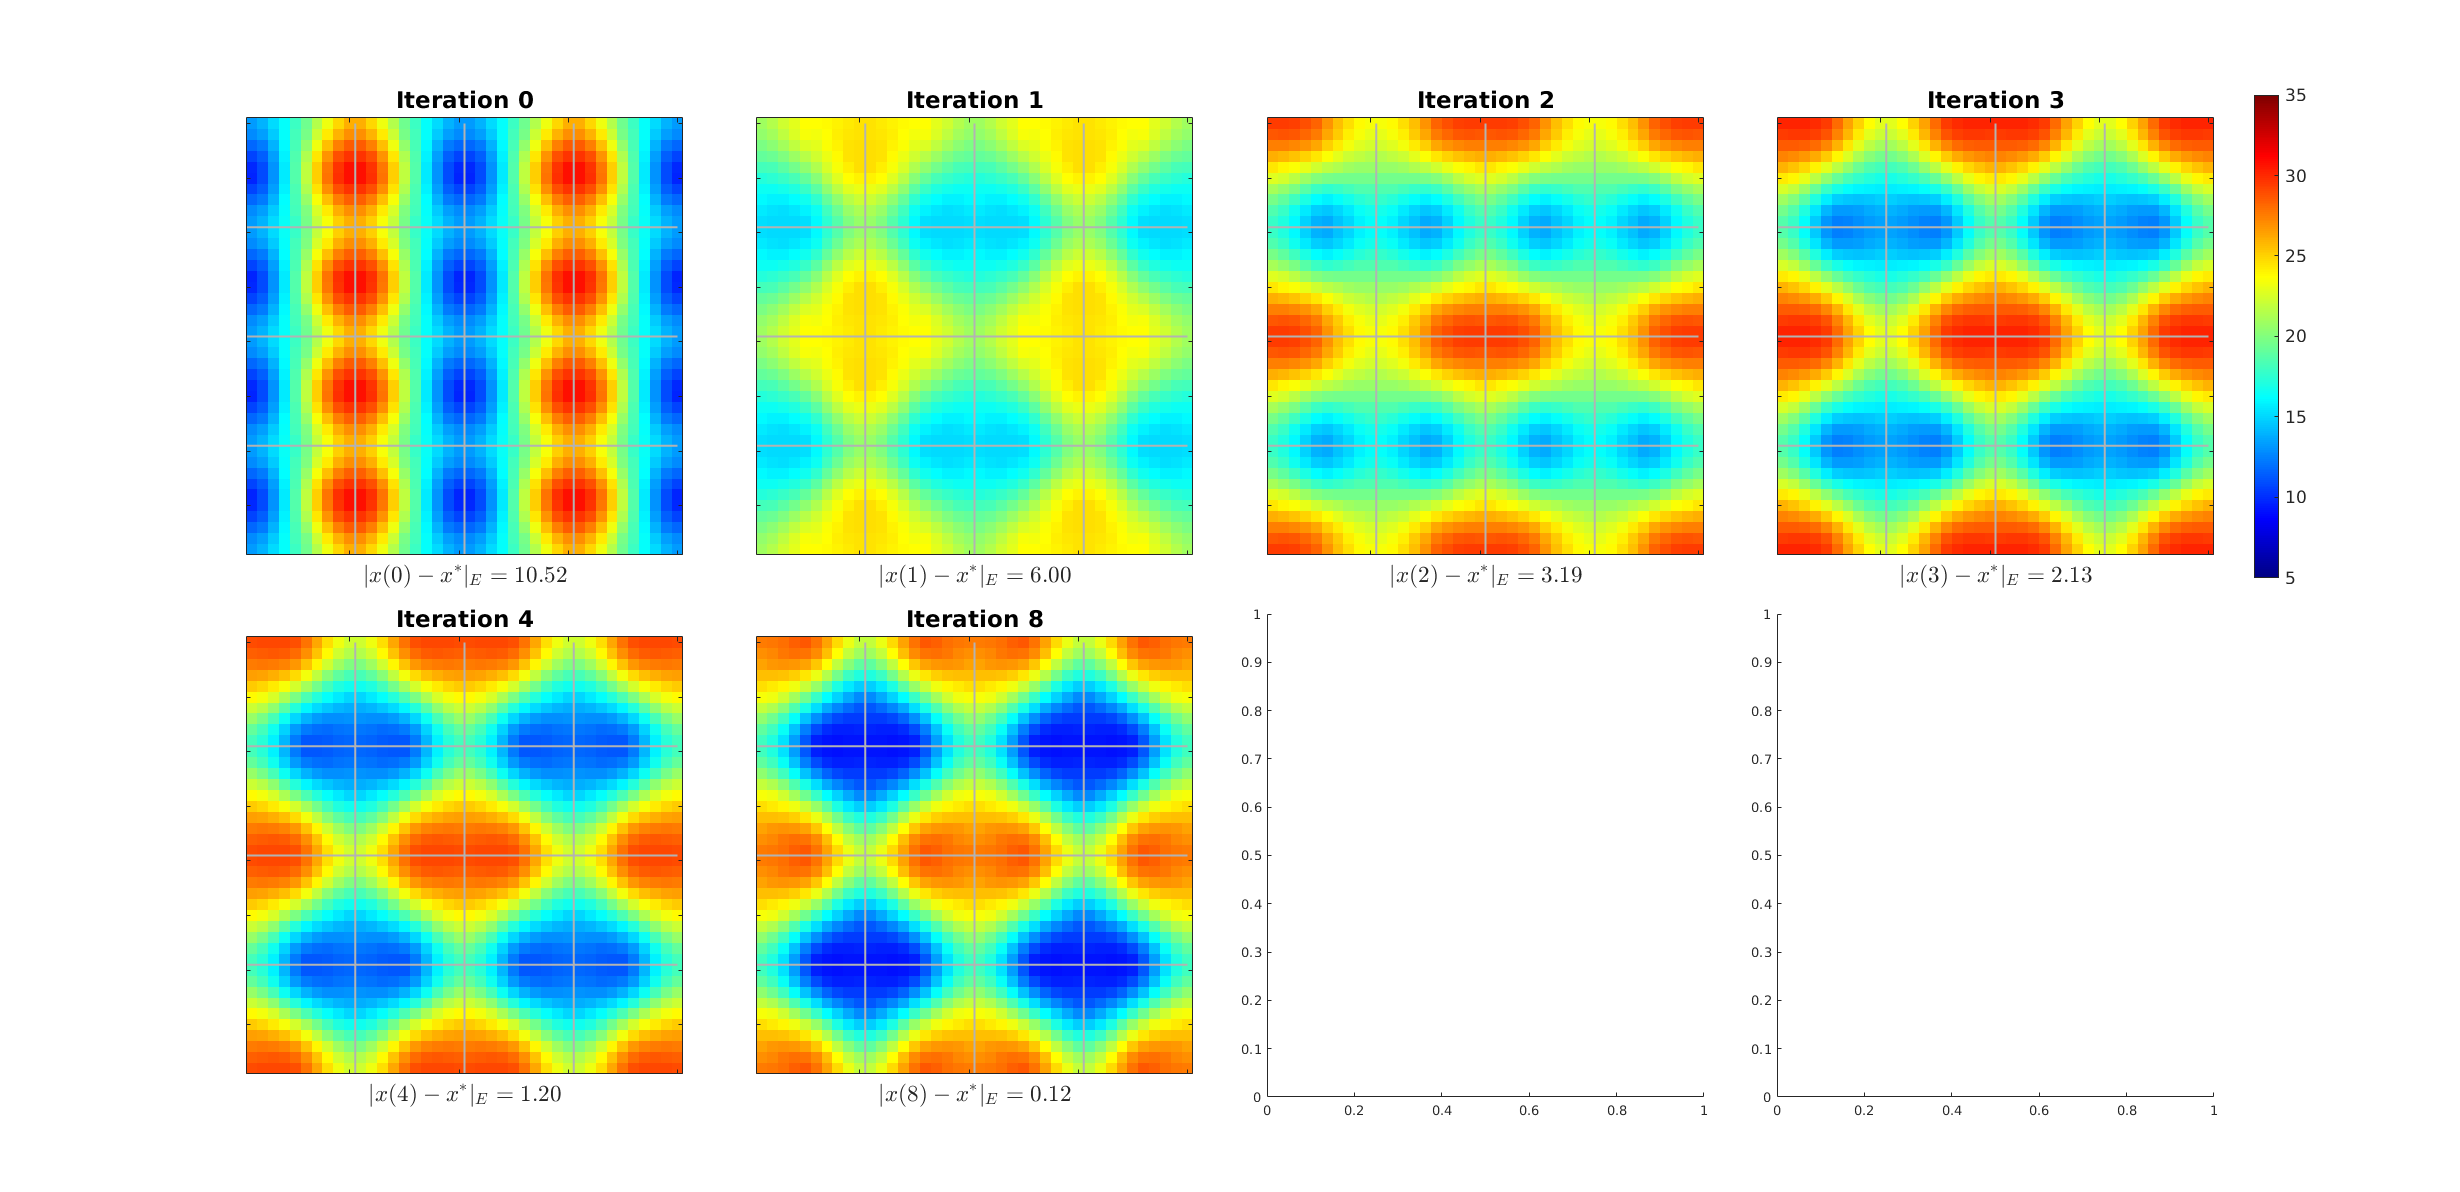

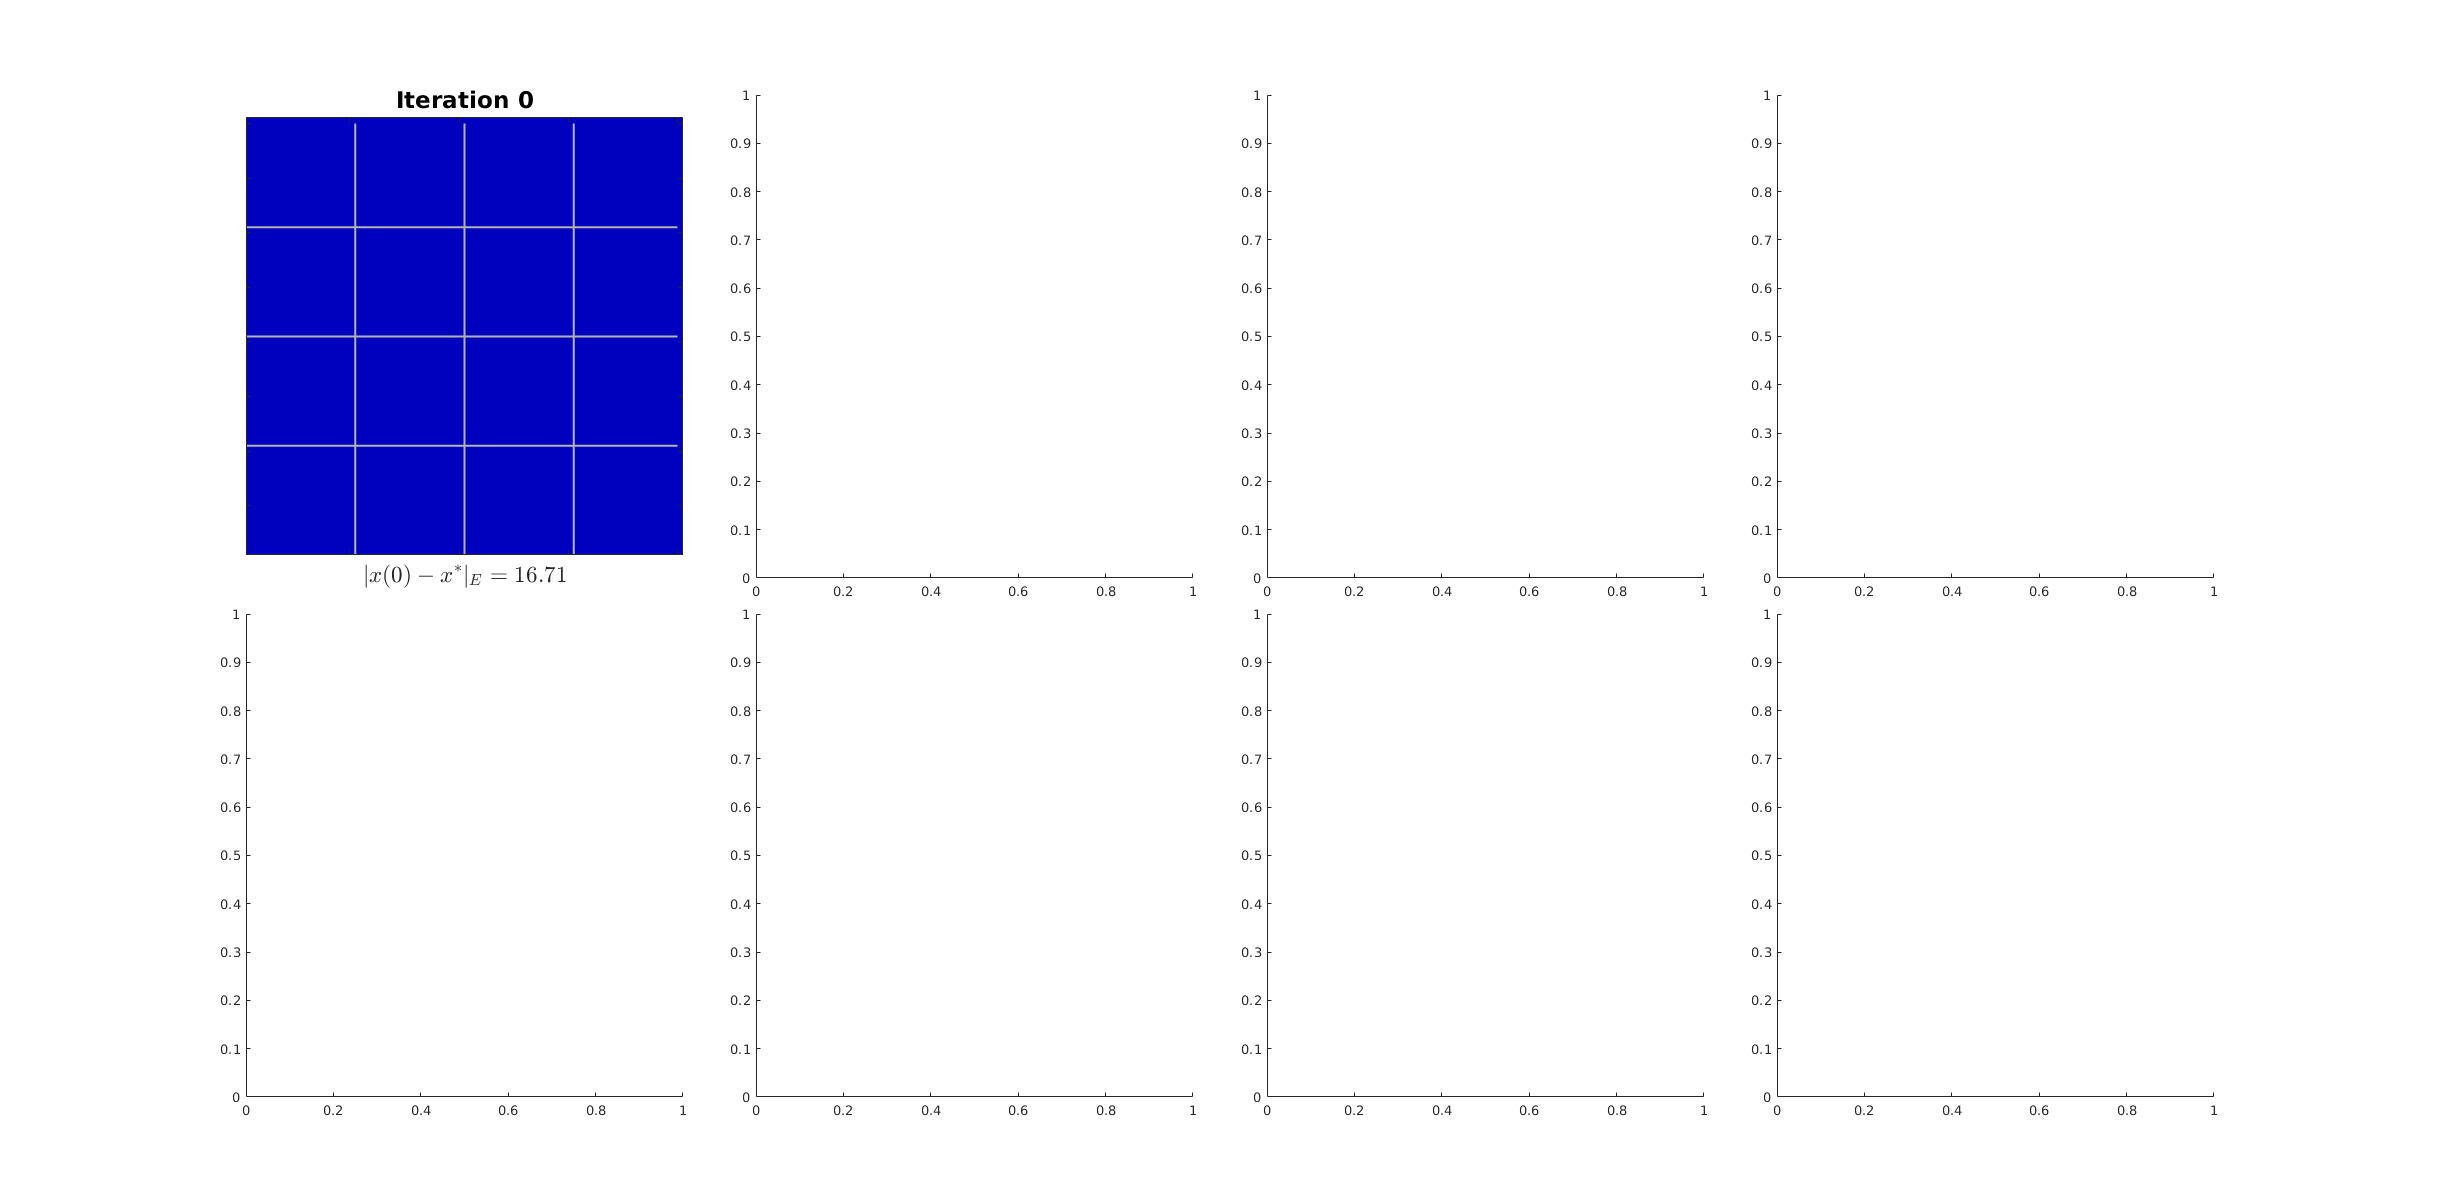

    Fig3.PaperUnits = 'centimeters';
    Fig3.PaperSize = [36,28];
    Fig3.PaperOrientation = "landscape";
    exportgraphics(Fig3,[FigurePaperPath FigName1 '.eps'],'Resolution',300)
end

Make an extra fig for epoc 1-8 anyway...

Fig3a = figure("Name",sprintf('%.1f',AngleInpt),'units','normalized','outerposition',[0,0,0.6,0.55]);%figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.5,0.4]);

TestInd = 1;
Panel1 = 2; Panel2 = 4;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.06 .06],[.08 .08],[.10 .10]);
LDEEpoOut = LDEOutAll{TestInd};
CaxeAll{1} = [repmat([0 70],5,1);repmat([5 43],6,1);];
%Caxe = [repmat([0 50],4,1);repmat([0 35],4,1)];
CaxeAll{2} = [repmat([5 35],8,1); repmat([0 120],8,1)];
Caxe = CaxeAll{TestInd};
for Epoc = 2:9
    %subplot(2,6,EpocInd+6*(ICInd-1))
    LDEPlot = LDEEpoOut{Epoc};

    axes(ha(Epoc-1));
    ShowField(...
        LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('fE Iteration %d',Epoc-1), Caxe(Epoc,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    xlabel(sprintf('$$|x(%d) - x^*|_E = %.2f$$',...
        Epoc-1 , L2Diff_OneStepAll(TestInd,Epoc)/(sqrt(NPixX*NPixY))),...
        'Interpreter',"latex")

%     axes(ha(Epoc+8));
%     ShowField(...
%         LDEPlot.I,...
%         1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
%         sprintf('fI Iteration %d',Epoc-1), Caxe(Epoc+8,:)) % last input may catgorized cbar: ,, [5 60]
%     set(gca,'fontsize',16)
%     set(gca,'YTickLabel',[]);
%     set(gca,'XTickLabel',[]);
end

save and print Fig3a

FigName2 = sprintf('Figure3aExp_%ddeg_%.1fKI',AngleInpt,(IKp.Slope)^2);
savefig(Fig3a,[FigurePaperPath FigName2 '.fig']);


Print Figs

Fig3a.PaperUnits = 'centimeters';
Fig3a.PaperSize = [36,36];
Fig3a.PaperOrientation = "landscape";
exportgraphics(Fig3a,[FigurePaperPath FigName2 '.pdf'],'Resolution',300)

Investigate the first one

PixX = [16, 20, 20]; PixY = [21, 21, 26];
for TestId = 1:length(PixX)
    XX = PixX(TestId); YY = PixY(TestId);
    PixInd = YY + (XX-1)*(N_HCOut*NPixY);
    LDE0 = LDEEpoOut{1}; LDE1 = LDEEpoOut{2};
    % get all quantities we concern
    Thrsld = 70; Highist = [100,97];
    IKL = InhKill(LDE0.I, Thrsld, Highist);
    L4SE = C_SS_mean*LDE0.S + C_SC_mean*LDE0.C ;
    L4CE = C_CS_mean*LDE0.S + C_CC_mean*LDE0.C ;
    L4SI = C_SI_mean*IKL ;
    L4CI = C_CI_mean*IKL ; % L4 input ends here
    
    L6CInpt = PixL6Ctgr * L6C_Drive_Grating' * 1e3;
    L6SInpt = PixL6Ctgr * L6S_Drive_Grating' * 1e3;
    LGNSInput = PixLGNCtgr * LGNS_biphase'* 1e3;
    
    fprintf('Pix location: X%d, Y%d\n', XX, YY)
    fprintf('Initial Frs: fE = %.1f, fI = %.1f\n',LDE0.S(PixInd)*(1-CplxR)+LDE0.C(PixInd)*CplxR, LDE0.I(PixInd));
    fprintf('Iter1 Frs: fE = %.1f, fI = %.1f\n',LDE1.S(PixInd)*(1-CplxR)+LDE1.C(PixInd)*CplxR, LDE1.I(PixInd));
    fprintf('Total L4 inpt (#sp/s): S<-E = %.1f, S<-I = %.1f, C<-E = %.1f, C<-I = %.1f\n', ...
        L4SE(PixInd), L4SI(PixInd), L4CE(PixInd), L4CI(PixInd))
    fprintf('Total L6 inpt (#sp/s): S<-L6 = %.1f, C<-L6 = %.1f\n', L6SInpt(PixInd), L6CInpt(PixInd))
    fprintf('Total LGN inpt to S (#sp/s): S<-LGNon = %.1f, S<-LGNoff = %.1f\n', LGNSInput(PixInd,1), LGNSInput(PixInd,2))
    fprintf('Total LGN inpt to C (#sp/s): C<-LGN = %.1f\n', 45*N_Clgn)
end